Q1-2

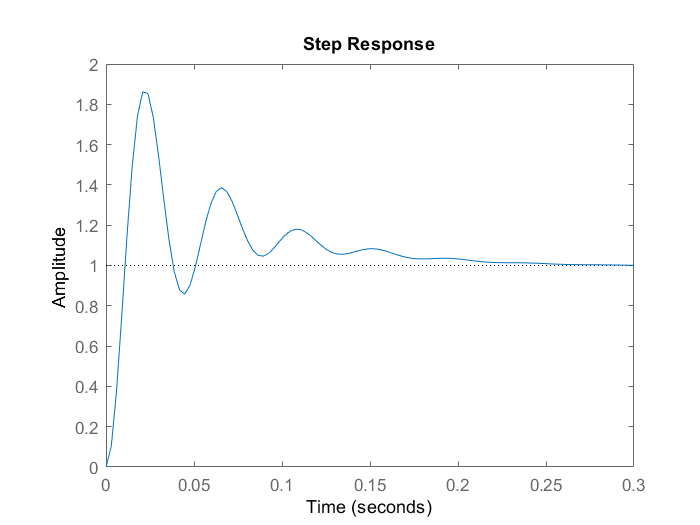

A=[0 1 0;1.9*10^3 0 2.5*10^4; 0 0 -87];
B=[0;0;8.7];
C=[1 0 0];
D=0;
sys=ss(A,B,C,D);
G=tf(sys);
Gc=tf([1925 64095.8 518000],[1 16567 0]);
T=feedback(series(Gc,G),1);
step(T);

stepinfo(T)

ans = struct with fields:
        RiseTime: 0.0071
    SettlingTime: 0.2122
     SettlingMin: 0.8584
     SettlingMax: 1.8622
       Overshoot: 86.2166
      Undershoot: 0
            Peak: 1.8622
        PeakTime: 0.0209


Q3

% tustin
Gc_t_1=c2d(Gc,0.1,'tustin');    % T=0.1s
Gc_t_2=c2d(Gc,0.01,'tustin');    % T=0.01s
Gc_t_3=c2d(Gc,0.001,'tustin');    % T=0.001s
% matched
Gc_m_1=c2d(Gc,0.1,'matched');    % T=0.1s
Gc_m_2=c2d(Gc,0.01,'matched');    % T=0.01s
Gc_m_3=c2d(Gc,0.001,'matched');    % T=0.001s

Q4

Gz=c2d(G,0.001)


Gz =
 
  3.548e-05 z^2 + 0.0001389 z + 3.397e-05
  ---------------------------------------
    z^3 - 2.919 z^2 + 2.835 z - 0.9167
 
Sample time: 0.001 seconds
Discrete-time transfer function.



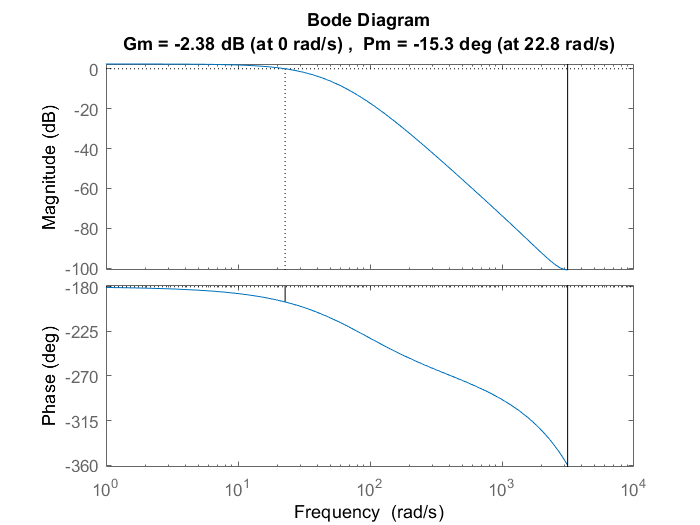

margin(Gz)

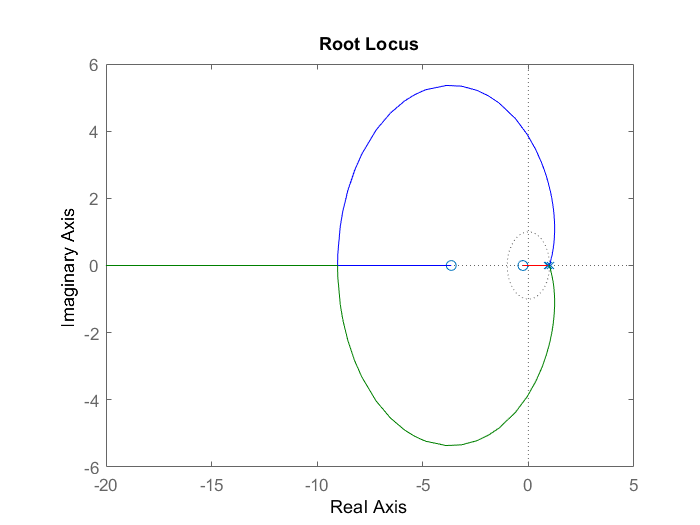

rlocus(Gz)

Q6

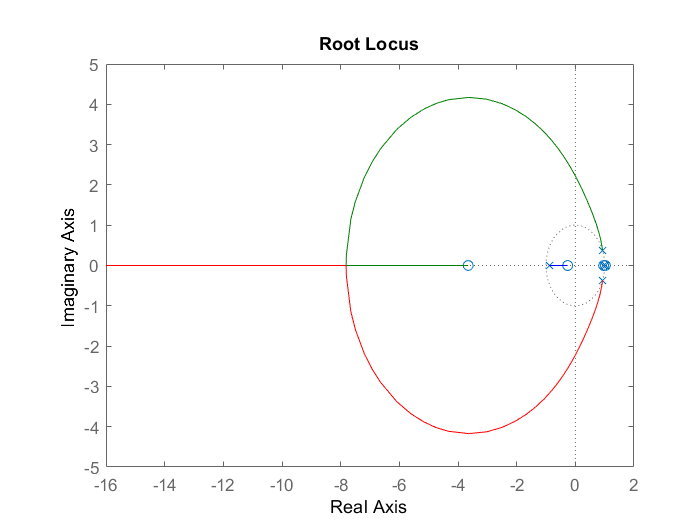

Gcz=tf([1288 -2563 1274],[1 -0.088 -0.912],0.001);
Tz=feedback(series(Gcz,Gz),1);
rlocus(Tz)

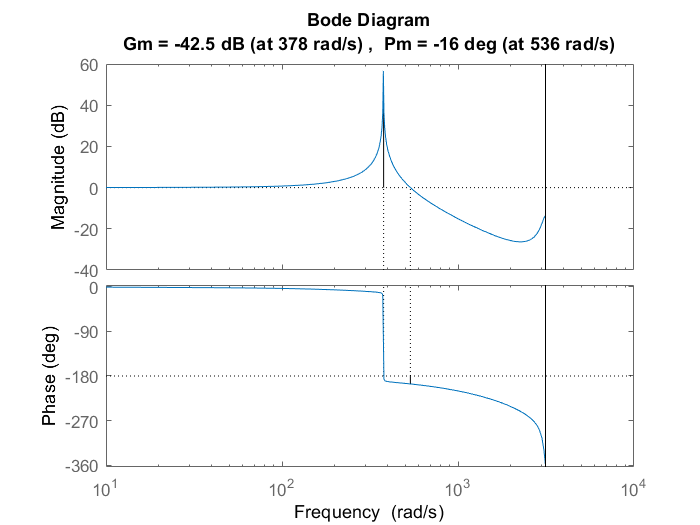

margin(Tz)

Q9

sys_discrete=c2d(sys,0.001);
G_d = sys_discrete.A

G_d =     1.0010    0.0010    0.0121
    1.9006    1.0010   23.9511
         0         0    0.9167


H_d = sys_discrete.B

H_d =     0.0000
    0.1057
    0.0083


C_d = sys_discrete.C

C_d =      1     0     0


D_d = sys_discrete.D

D_d = 0

ControllabilityMatrix=ctrb(G_d,H_d)

ControllabilityMatrix =     0.0000    0.0002    0.0006
    0.1057    0.3054    0.4891
    0.0083    0.0076    0.0070


ObservabilityMatrix=obsv(G_d,C_d);
rank(ControllabilityMatrix)   % Is Controllable

ans = 3

rank(ObservabilityMatrix)    % Is Observable

ans = 3

Q10

W=[2.84 -2.92 1; -2.92 1 0; 1 0 0];
M=[H_d G_d*H_d G_d^2*H_d];
T=M*W;
k_hat=[0.92 -2.84 2.92];
k=k_hat*inv(T)

k = 	1.0e+03 *

    4.8057    0.0096    0.2083


Q11

N=[C_d; C_d*G_d; C_d*G_d^2];
Tl=W*N;
L=inv(Tl)*k_hat'

L = 	1.0e+03 *

    0.0029
    2.3562
    0.0335


P = -85.5750